**Q4. (a) Use the RiskMetrics or Historical Simulation approach to compute the one-day ahead return-VaR for one of the stocks over the period 03/01/22-30/12/22 and conduct backtesting.**

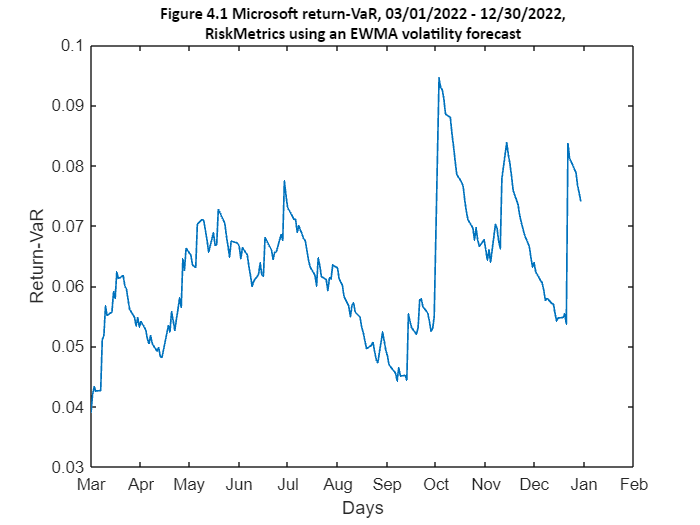

%Task 4a
%Clear the Workspace.
clear;
%Setting default directory
cd('Set location of your default directory');

file_location = 'Your file location\Data set 1';
[msft_price, date_3] = log_pop(file_location, 'MSFT.xlsx', 'MSFT', 'F2:F3022');


%Computing the return.
ret = msft_price(2:end,1)-msft_price(1:end-1,1);

% Adjusting date.
adjDate_1 = date_3(2:end,1);

%Forecasting VaR using custom RiskMetric function
[fvar] = RiskMetric(ret,212);
 
% Measuring the sample size.
num_ret = size(ret,1);

% Plotting a graph of the VaR.
plot(adjDate_1(num_ret-211:num_ret,1),fvar,'LineWidth',1);
% Adding a title.
title({'Figure 4.1 Microsoft return-VaR, 03/01/2022 - 12/30/2022,', ...
    'RiskMetrics using an EWMA volatility forecast'}, ...
    'FontSize',10,'FontName','Calibri');
ylabel("Return-VaR");
xlabel("Days");

% Adding date ticks
datetick('x','mmm');
% Saving the current graph
% saveas(gcf,"fig41.jpg"); % Uncomment to save the graph

% Backtesting

%Creating a varbacktest object.
vbt = varbacktest(ret(end-211:end,1),fvar,'VaRLevel',0.99); 
% Apply the POF test.
POF_TestResults = pof(vbt,'TestLevel',0.99);
% Apply the CCI test.
CCI_TestResults = cci(vbt,'TestLevel',0.99);
 %Applying the CCI test.
CC_TestResults = cc(vbt,'TestLevel',0.99);

**Q4. (b) Use the RiskMetrics or Historical Simulation approach to compute the one-day ahead return-VaR for an equally weighted portfolio of the four stocks over the period 03/01/22-30/12/22 and conduct backtesting.**

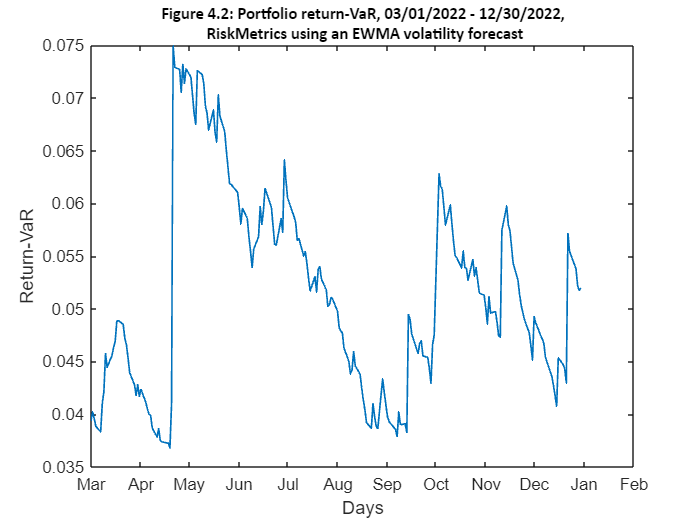

%Task 4b
clear;

% Setting location of the folder where the files are present
file_location = 'C:\Users\Krane\Desktop\Matlab assignment\Data set 1';
[portfolio_1(:,1),date_4] = log_pop(file_location, 'JNJ.xlsx','JNJ', 'F2:F3022');

% Since the dates for the other dataset will be the same, so not getting the dates
[portfolio_1(:,2),~] = log_pop(file_location, 'MSFT.xlsx','MSFT', 'F2:F3022');
[portfolio_1(:,3),~] = log_pop(file_location, 'NFLX.xlsx','NFLX', 'F2:F3022');
[portfolio_1(:,4),~] = log_pop(file_location, 'NKE.xlsx','NKE', 'F2:F3022');

%Computing the return of the portfolio
port_ret = portfolio_1(2:end,:)-portfolio_1(1:end-1,:);

% Adjusting date.
adjDdate_2 = date_4(2:end,1);

%Forecasting VaR using custom RiskMetric function
fvarPort = RiskMetric(port_ret,212);

% Measuring the sample size.
num_portRet = size(port_ret,1);

%Plotting a graph of the VaR.
plot(adjDdate_2(num_portRet-211:num_portRet,1),fvarPort,'LineWidth',1);
%Adding a title.
title({'Figure 4.2: Portfolio return-VaR, 03/01/2022 - 12/30/2022,' ...
    ' RiskMetrics using an EWMA volatility forecast'}, ...
    'FontSize',10,'FontName','Calibri');
ylabel("Return-VaR");
xlabel("Days");
% Adding date ticks.
datetick('x','mmm');
% Saving the current graph
saveas(gcf,"fig42.jpg"); % Uncomment to save the graph

% Backtesting

vbt_port = varbacktest(port_ret(end-211:end,1),fvarPort,'VaRLevel',0.99); %Create a varbacktest object.
%Apply the POF test.
POF_portTR = pof(vbt_port,'TestLevel',0.99);

%Applying the CCI test.
CCI_portTR = cci(vbt_port,'TestLevel',0.99);
%Applying the CC test.
CC_portTR = cc(vbt_port,'TestLevel',0.99);
